# Linear Control Design II - Group Work Problem Module 6 Solution

## Description		

Figure 1 shows an aircraft in lateral motion where the movements are yaw (rotation around the vertical axis) and roll (rotation around the longitudinal axis). The lateral motion of an aircraft takes primarily place in the horizontal plane. 

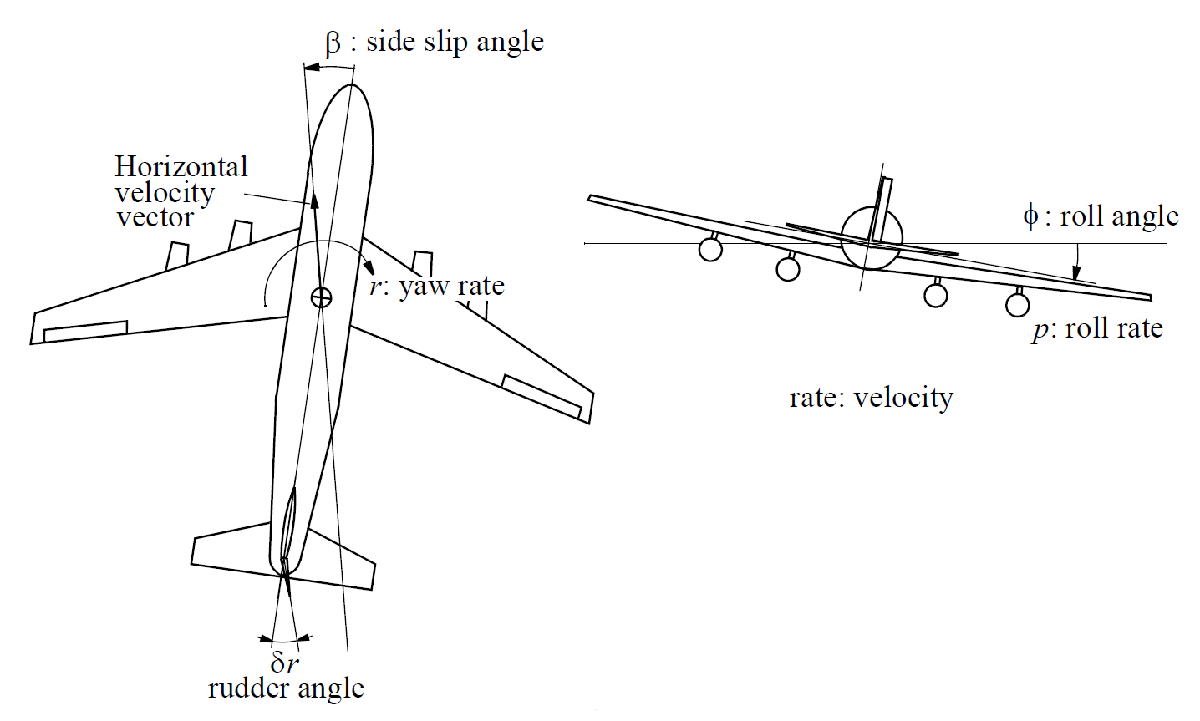  

			Figure 1: Lateral dynamics of a Boeing 747:	

A linearized state space model of the lateral dynamics of a Boeing 747 in altitude 40000 ft and speed 774 ft/sec (850 km/h) is shown below:

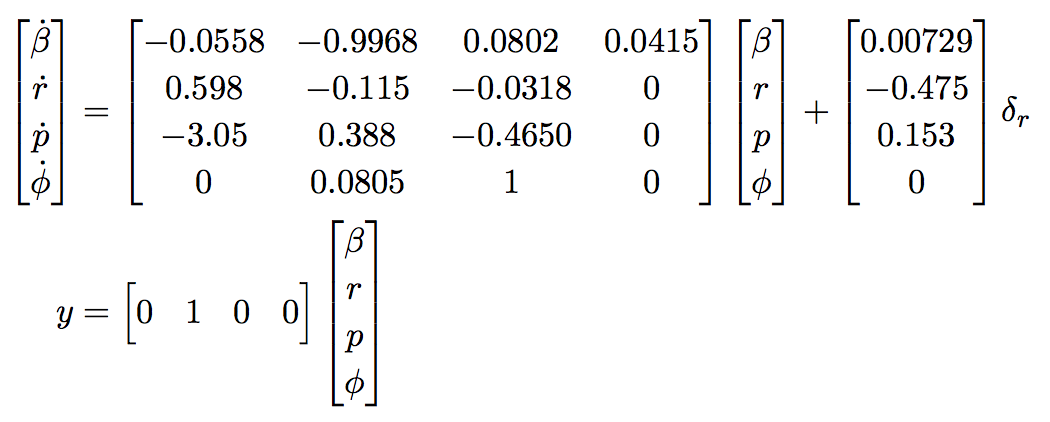

where $\beta$ is the side-slip angle (rad), $r$is the yaw rate (rad/s), $p$ is the roll rate (rad/s), $\varphi$ is the roll angle (rad), and $\delta_r$ is the rudder deflection (rad). 

% Define system matrices:
A = [-0.0558 -0.9968  0.0802  0.0415;
      0.598  -0.115  -0.0318  0;
     -3.050   0.388  -0.4650  0;
      0       0.0805  1       0]

A =    -0.0558   -0.9968    0.0802    0.0415
    0.5980   -0.1150   -0.0318         0
   -3.0500    0.3880   -0.4650         0
         0    0.0805    1.0000         0

B = [0.00729; -0.475; 0.153; 0]

B =     0.0073
   -0.4750
    0.1530
         0

C = [0 1 0 0]

C =      0     1     0     0

D = 0;

This assignment guides you through the analysis of the aircraft’s lateral dynamics in terms of natural modes and system responses to non-zero initial conditions and external inputs. 

**Problem 1** Calculate the eigenvalues of the system dynamical matrix A, and based on those identify, if relevant, the time constants, natural frequencies and damping ratios. 

**Solution****:**

The eigenvalues are found by solving the characteristic equation:


$$\mathbf{P}_{ch,\mathbf{A}} = \det(\lambda \mathbf{I} - \mathbf{A})=0$$


which yields the following eigenvalues:


$$\lambda_1 = -0.0073, \lambda_2 = -0.5627, \lambda_{3,4} = -0.0329 \pm 0.9467i$$


% In Matlab, the eigenvalues can be easily found using as:
evals = eig(A)

evals =   -0.0329 + 0.9467i
  -0.0329 - 0.9467i
  -0.5627 + 0.0000i
  -0.0073 + 0.0000i

Note that all the eigenvalues have negative real part, so they lie in the left half complex plane. This ensures the asymptotic stability of the system.

The time constants for the real eigenvalues can be found using the formula, $t_i = -1/\lambda _i$, (see page 74 of the textbook) which in this case gives the time constants: $t_{1}  = 137.4010$ and $t_{2} = 1.7773$. 

For the complex conjugated pair of eigenvalues the system will have a natural frequency and a damping ratio given by $\omega_n = \sqrt{\alpha^2+\beta^2}$ and $\zeta = -\alpha/ \sqrt{\alpha^2 + \beta^2}$ (see page 75 of the textbook). In this case the natural frequency and damping ratios are: $\omega_n = 0.9472$ and $\zeta = 0.0348$. 

% In Matlab, the time constants, natural frequencies and damping ratios are
% found using the damp-function:
damp(A)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -3.29e-02 + 9.47e-01i     3.48e-02       9.47e-01          3.04e+01    
 -3.29e-02 - 9.47e-01i     3.48e-02       9.47e-01          3.04e+01    
 -5.63e-01                 1.00e+00       5.63e-01          1.78e+00    
 -7.28e-03                 1.00e+00       7.28e-03          1.37e+02    



% --- or by manual calculation:
% time constants s74-75
tau_i = [-1/evals(3) -1/evals(4)]'

tau_i =     1.7773
  137.4010

% natural frequencies 
omega_n = abs(evals(1))

omega_n = 0.9472

% damping ratios
zeta = -real(evals(1))/omega_n(1)

zeta = 0.0348

**Problem 2** Based on the calculated eigenvalues determine the natural modes (also known as eigenmodes) of the system. 

**Solution:**

The natural modes of the system can be written from the eigenvalues as (see page 69 of the textbook):

$e^{-0.0073t}$, $e^{-0.5627t}$, and $e^{(-0.0329\pm 0.947i)t}$ or using Euler decomposition$e^{-0.0329t} (\cos(0.947t) \pm i \sin(0.947t))$

% Plot the temporal evolution of the eigenmodes
t_t1 = 0:1:1000;
t_t2 = 0:0.01:10;
t_wn = 0:0.1:150;

E1 = exp(evals(4)*t_t1);
E2 = exp(evals(3)*t_t2);
%E3 = exp(real(evals(1))*t_wn).*(cos(imag(evals(1))*t_wn) + 1i*sin(imag(evals(1))*t_wn));
%E4 = exp(real(evals(1))*t_wn).*(cos(imag(evals(1))*t_wn) - 1i*sin(imag(evals(1))*t_wn));
E3 = exp(evals(1)*t_wn)

E3 =   Columns 1 through 526
   1.0000 + 0.0000i   0.9922 + 0.0942i   0.9757 + 0.1870i   0.9505 + 0.2774i   0.9170 + 0.3648i   0.8755 + 0.4484i   0.8265 + 0.5274i   0.7704 + 0.6012i   0.7078 + 0.6691i   0.6393 + 0.7306i   0.5655 + 0.7852i   0.4871 + 0.8324i   0.4049 + 0.8718i   0.3196 + 0.9032i   0.2321 + 0.9263i   0.1430 + 0.9410i   0.0532 + 0.9472i  -0.0364 + 0.9448i  -0.1251 + 0.9341i  -0.2122 + 0.9151i  -0.2967 + 0.8880i  -0.3781 + 0.8531i  -0.4555 + 0.8109i  -0.5284 + 0.7617i  -0.5961 + 0.7060i  -0.6580 + 0.6444i  -0.7136 + 0.5774i  -0.7625 + 0.5057i  -0.8042 + 0.4299i  -0.8385 + 0.3508i  -0.8650 + 0.2691i  -0.8837 + 0.1855i  -0.8943 + 0.1009i  -0.8969 + 0.0158i  -0.8914 - 0.0688i  -0.8780 - 0.1522i  -0.8569 - 0.2338i  -0.8282 - 0.3127i  -0.7923 - 0.3883i  -0.7496 - 0.4599i  -0.7005 - 0.5270i  -0.6454 - 0.5889i  -0.5849 - 0.6452i  -0.5196 - 0.6953i  -0.4500 - 0.7388i  -0.3769 - 0.7755i  -0.3010 - 0.8050i  -0.2228 - 0.8271i  -0.1431 - 0.8417i  -0.0627 - 0.8486i   0.0177 - 0.8480i  

E4 = exp(evals(2)*t_wn)

E4 =   Columns 1 through 526
   1.0000 + 0.0000i   0.9922 - 0.0942i   0.9757 - 0.1870i   0.9505 - 0.2774i   0.9170 - 0.3648i   0.8755 - 0.4484i   0.8265 - 0.5274i   0.7704 - 0.6012i   0.7078 - 0.6691i   0.6393 - 0.7306i   0.5655 - 0.7852i   0.4871 - 0.8324i   0.4049 - 0.8718i   0.3196 - 0.9032i   0.2321 - 0.9263i   0.1430 - 0.9410i   0.0532 - 0.9472i  -0.0364 - 0.9448i  -0.1251 - 0.9341i  -0.2122 - 0.9151i  -0.2967 - 0.8880i  -0.3781 - 0.8531i  -0.4555 - 0.8109i  -0.5284 - 0.7617i  -0.5961 - 0.7060i  -0.6580 - 0.6444i  -0.7136 - 0.5774i  -0.7625 - 0.5057i  -0.8042 - 0.4299i  -0.8385 - 0.3508i  -0.8650 - 0.2691i  -0.8837 - 0.1855i  -0.8943 - 0.1009i  -0.8969 - 0.0158i  -0.8914 + 0.0688i  -0.8780 + 0.1522i  -0.8569 + 0.2338i  -0.8282 + 0.3127i  -0.7923 + 0.3883i  -0.7496 + 0.4599i  -0.7005 + 0.5270i  -0.6454 + 0.5889i  -0.5849 + 0.6452i  -0.5196 + 0.6953i  -0.4500 + 0.7388i  -0.3769 + 0.7755i  -0.3010 + 0.8050i  -0.2228 + 0.8271i  -0.1431 + 0.8417i  -0.0627 + 0.8486i   0.0177 + 0.8480i  

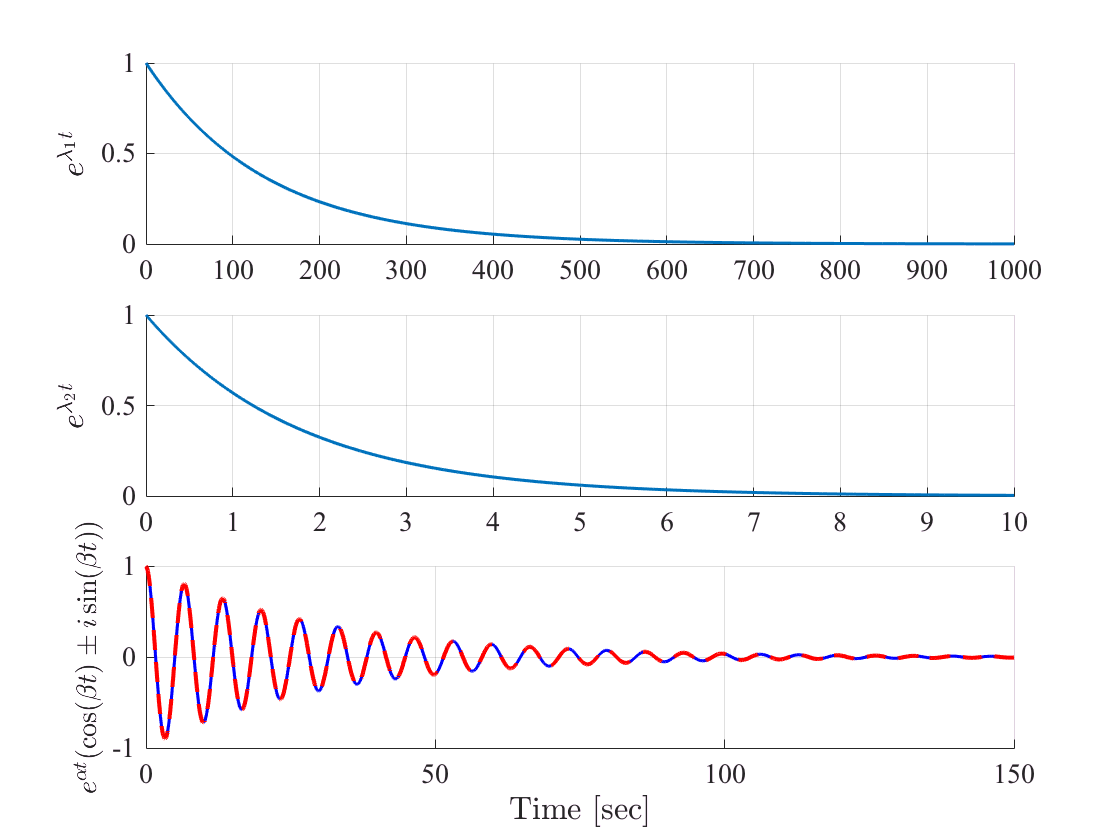


figure, h1 = subplot(3,1,1); set(h1,'FontSize',14,'FontName','times');
hold on, grid on
plot(t_t1,E1,'LineWidth',1.5)
ylabel('$e^{\lambda_1 t}$','FontSize',16,'FontName','times','Interpreter','latex')
h2 = subplot(3,1,2); set(h2,'FontSize',14,'FontName','times');
hold on, grid on
plot(t_t2,E2,'LineWidth',1.5)
ylabel('$e^{\lambda_2 t}$','FontSize',16,'FontName','times','Interpreter','latex')
h3 = subplot(3,1,3); set(h3,'FontSize',14,'FontName','times');
hold on, grid on
plot(t_wn,real(E3),'b',t_wn,real(E4),'--r','LineWidth',1.5)
ylabel('$e^{\alpha t}(\cos(\beta t) \pm i \sin(\beta t))$','FontSize',14,'FontName','times','Interpreter','latex')
xlabel('Time [sec]','FontSize',16,'FontName','times','Interpreter','latex')

The eigenstructure of the lateral dynamics is usually represented by two real eigenvalues and one pair of complex conjugate eigenvalues. The three lateral modes are referred to as ***roll subsidence***, ***spiral*** and ***dutch roll***. 

- The **roll subsidence** **mode** is non-oscillatory and is usually decoupled from the spiral mode and from the dutch roll modes. In rolling motion the wing experiences a component of velocity normal to the wing resulting in a small increase in the angle of attack on the down- going wing and a small decrease on the up-going wing thus, generating a lift difference over the wing span. Moreover, the lift difference gives rise to a restoring roll moment represented by the roll subsidence mode. 

- The **spiral mode** is usually slow non-oscillatory and involves complex coupled motion in roll, yaw and side-slip angle. The spiral mode is usually excited by a disturbance in side-slip which is typically followed by a disturbance in roll. The side-slip angle generates a force on the tail fin, which in turn generates a yawing moment in the direction of the side-slip angle. The yawing motion generates increased differential lift across the wing span inducing increased roll moment and thereby, aggravates the situation. 

- The** dutch roll mode** is a damped oscillation and the motion is a complex interaction between the three lateral degrees of freedom. The dutch roll mode makes the wing tip move in an elliptic pattern seen from the side parallel to the wing. 

**Problem 3** Based on the found eigenvalues and the aforementioned modes, associate the eigenvalues to the corresponding mode of the lateral dynamics. 	

**Solution:**

From the description three lateral modes have been described two non oscillating; **roll subsidence mode** and** spiral mode**, and one with damped oscillation **Dutch roll mode.** This directly leads to the conclusion that the Dutch roll mode is associated with the complex conjugated pair of eigenvalues. 

            **Dutch roll mode:** $e^{-0.0329t} (\cos(0.947t) \pm i \sin(0.947t))$

The Spiral mode is described as the slow non-oscillatory thus the eigenmode with the larger of the two time constants (smaller eigenvalue) is associated with the spiral mode.

            **Spiral mode:** $e^{-0.0073t}$

The roll subsidence mode is described as non-oscillatory and thus the eigenmode with the smaller of the two time constants (larger eigenvalue) is associated with the roll subsidence mode.

            **Roll subsidence mode:** $e^{-0.5627t}$

**Problem 4** Compute the modal matrix $\mathbf{M}_{lat}$of the system and discuss which natural modes contributes most and least to the dynamics of the state variables $\beta, r, p, \varphi$ (Make sure that your modal matrix has real elements)	

**Solution:**

The modal matrix is the matrix consisting of the eigenvectors of the system matrix A. These are found by solving the characteristic equation: 


$$\mathbf{P}_{ch,\mathbf{A}} = \det(\lambda \mathbf{I} - \mathbf{A})=0$$


And then substituting one at a time the $\lambda_i$into the equation: 


$$\mathbf{A}\mathbf{v}_i = \lambda_i \mathbf{v}_i \Rightarrow \mathbf{A}\mathbf{v}_i - \lambda_i \mathbf{v}_i = 0 \Rightarrow ( \lambda_i \mathbf{I}-\mathbf{A}) \mathbf{v}_i = 0$$


Matlab can do this calculation with: 	 

% M is the Modal matrix
% E is a diagonal matrix with the corresponding eigenvalues.
[M,E] = eig(A)

M =    0.1994 - 0.1063i   0.1994 + 0.1063i  -0.0172 + 0.0000i   0.0067 + 0.0000i
  -0.0780 - 0.1333i  -0.0780 + 0.1333i  -0.0118 + 0.0000i   0.0404 + 0.0000i
  -0.0165 + 0.6668i  -0.0165 - 0.6668i  -0.4895 + 0.0000i  -0.0105 + 0.0000i
   0.6930 + 0.0000i   0.6930 + 0.0000i   0.8717 + 0.0000i   0.9991 + 0.0000i

E =   -0.0329 + 0.9467i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0329 - 0.9467i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.5627 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0073 + 0.0000i

Two of the eigenvectors are complex and conjugates. To get the mode shapes, it is known from for example math 2 (Ole Christensen, Differential ligninger og uendelige raekker, chapter 2) that to obtain the real solutions for the system, the cosine with the real part of the complex eigenvector and the sine part with the imaginary part of the eigenvector is a solution and is independent from all the other solutions consisting of the other eigenvectors. 

This means that the following matrix $\mathbf{M}_{real}$ represents the real solutions and real mode shapes of the system. 

Mreal = [real(M(:,1)) imag(M(:,1)) M(:, 3:end)]

Mreal =     0.1994   -0.1063   -0.0172    0.0067
   -0.0780   -0.1333   -0.0118    0.0404
   -0.0165    0.6668   -0.4895   -0.0105
    0.6930         0    0.8717    0.9991

Looking at the columns of this matrix describes the 4 different mode shapes of the system. The first 2 is the oscillatory dutch roll motion, it is seen that the approximately evenly distributed elements in all 4 directions, means all the variables are excited during this motion. The third eigenvector corresponds to the roll subsidence mode, which affects the roll rate and the bank angle. Note different signs, meaning that the roll rate and bank angle is opposite, i.e., with bank to the right (positive $\varphi$), the roll rate is negative (to the left). The last mode is the spiral divergence mode, which almost only affects the bank angle. 

**Problem 5** Determine the transfer function from rudder deflection $\delta_r$ to yaw rate r, and calculate the Bode’s diagram. Which of the aforementioned modes are visible in the magnitude response of the Bode’s diagram? 		

**Solution:**

In the states-space description of equation, the input is $\delta_r$ and the output matrix $\mathbf{C}$ already selects the yaw rate $r$as the output. The transfer function can then be calculated as (see eq. (3.67) page 73): 


$$\mathbf{G}(s) = \mathbf{C}(s \mathbf{I} - \mathbf{A})^{-1} \mathbf{B} + \mathbf{D}$$


or using the matlab function ss2tf()-function. The transfer function is found as follows: 

[num,den] = ss2tf(A,B,C,D);
G = tf(num,den)


G =
 
     -0.475 s^3 - 0.2479 s^2 - 0.1187 s - 0.05633
  ---------------------------------------------------
  s^4 + 0.6358 s^3 + 0.9389 s^2 + 0.5116 s + 0.003674
 
Continuous-time transfer function.




% Another way to compute is by first defining the state-space system in Matlab
sys_ss = ss(A,B,C,D);
% and convert to a transfer function:
G = tf(sys_ss)


G =
 
     -0.475 s^3 - 0.2479 s^2 - 0.1187 s - 0.05633
  ---------------------------------------------------
  s^4 + 0.6358 s^3 + 0.9389 s^2 + 0.5116 s + 0.003674
 
Continuous-time transfer function.



The Bode Diagram is calculated as follows in MatLab:

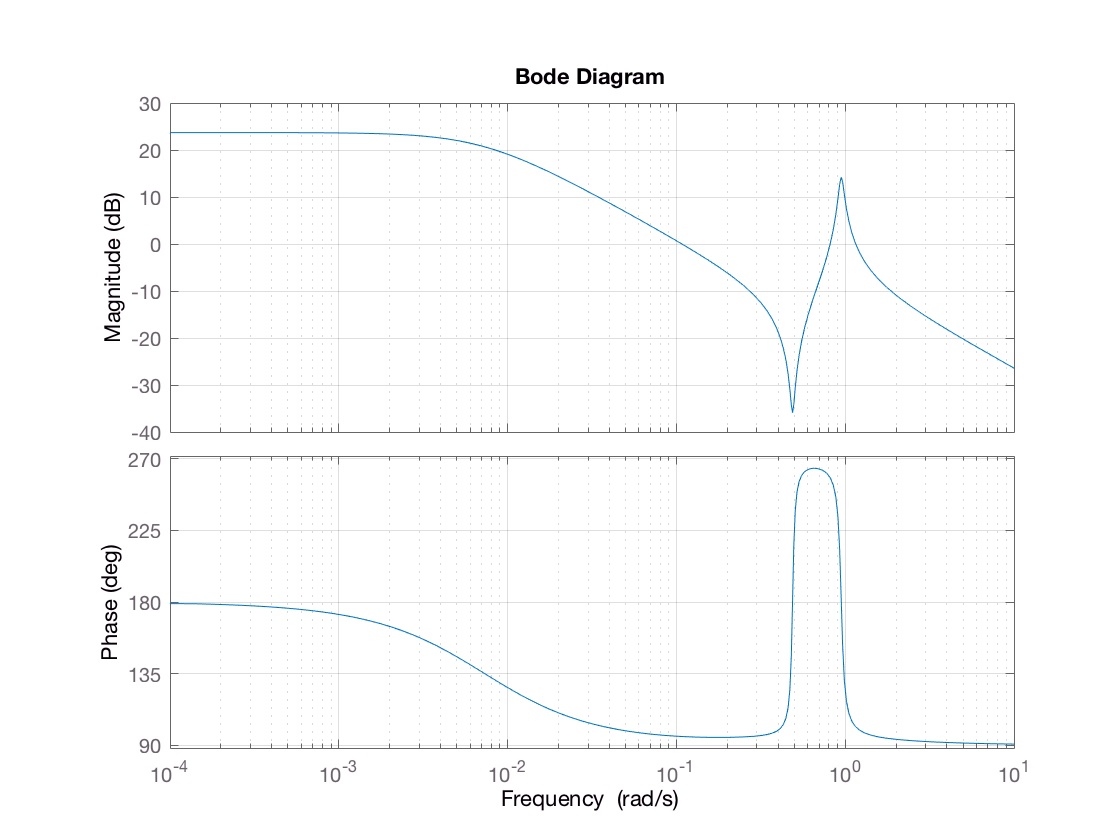

figure
bode(G)
grid on


% You can also call bode on the state-space system, i.e. 
% bode(sys_ss)

From the Bode plot it is clearly seen that there is a pole around $10^{-2}$ rad/s and there is a resonance peak (complex pole pair) at around$1$rad/s. Furthermore there is a anti-resonance (complex zero pair) around 0.5 rad/s. What is not clear from the plot is that there are another pole and zero around 0.5 rad/s, and since they are so close, they almost cancel each other. 

**Problem 6** Calculate the zero-state response for a step of 5 degrees in the rudder input. Analyse the response in connection with the modal analysis. 	

**Solution:**

Now that the transfer function is found it is possible to simulate a step on the rudder angle $\delta_r$ by using the step()-function on the transfer function. Making a step on the transfer function is the same as calculating the zero state response as the transfer function has the initial condition of the states as 0. 

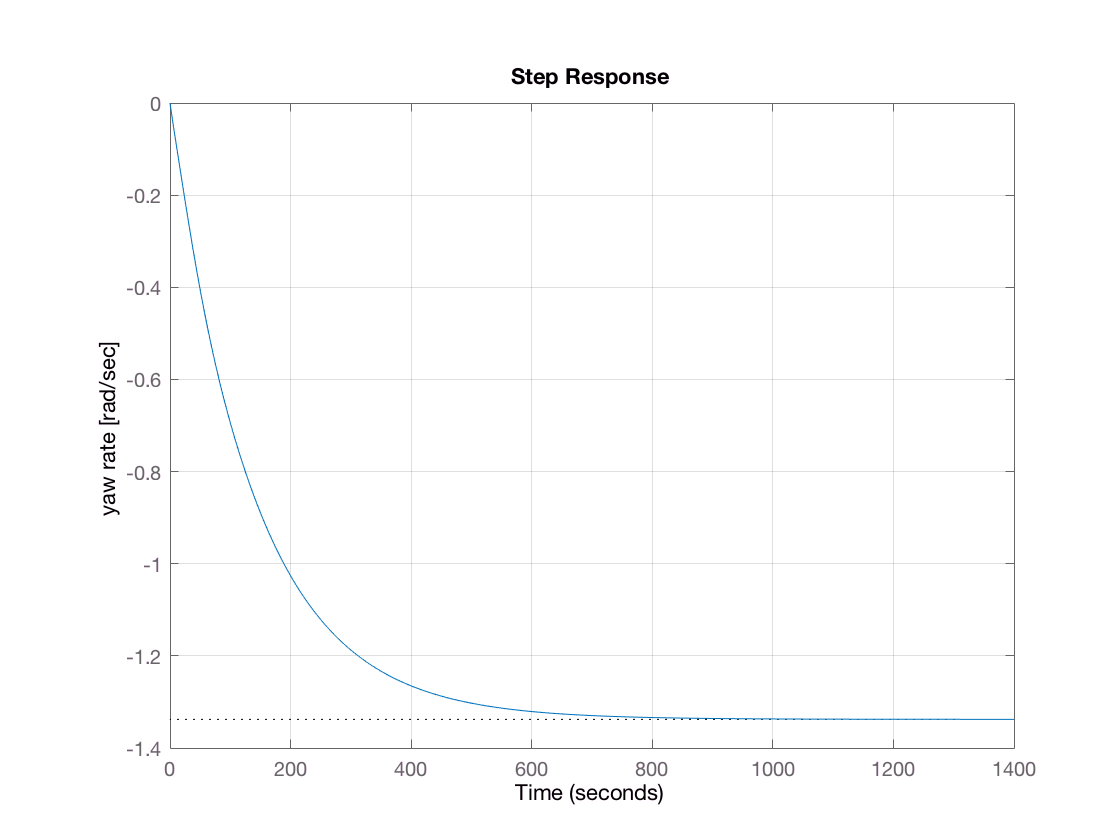

step_magnitude = 5*pi/180;
step(G * step_magnitude), grid
ylabel('yaw rate [rad/sec]');

The reason for the yaw rate to become negative is due to the sign of the corresponding constant (-0.475) in the B-matrix. Due to the size of this constant even small inputs result in large effects on the yaw rate. The behaviour of this input is dominated by the natural mode associated with the small real eigenvalue, as the plot shows only a decay with a high time constant. 

**Problem 7** Calculate the zero-input response for a side-slip initial angle $\beta_0 = 1$degree. Analyse the response in connection with the modal analysis. 	

**Solution:**

In this part the plane is oriented a little off the right course and is supposed to get back on track. As the zero input response is the evolution of the system to an initial condition of the states (see page 62 of the textbook) Using the Matlab lsim()-function it is possible to simulate the system with an initial value of the side slip of $\beta_0 = 1 \text{deg} = \frac{\pi}{180} \text{rad}$. Remember to set the u-input in lsim() to zeroes.

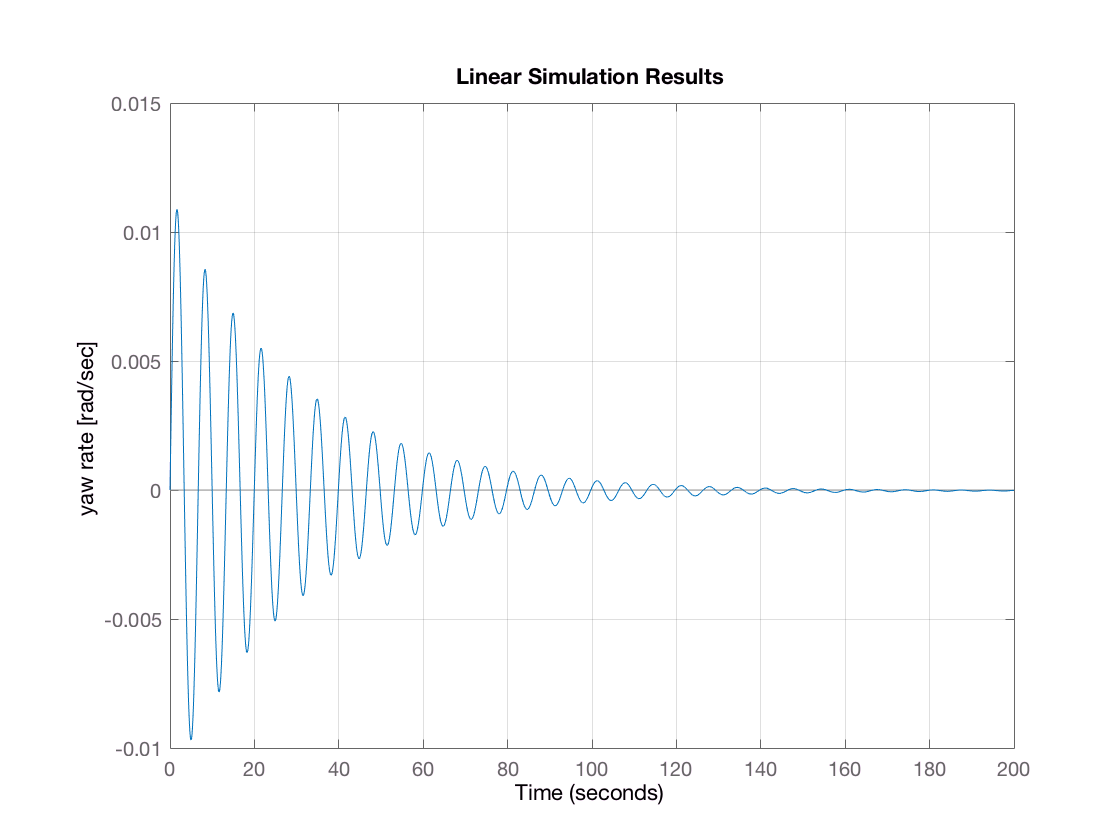

%% Q7 Reponse of a side slip
figure
t = 0:.1:200;
u = zeros(length(t),1);
beta0 = 1*pi/180;
x0 = [beta0 0 0 0]';
lsim(A,B,C,D,u,t,x0),grid
ylabel('yaw rate [rad/sec]');

It takes long time for the system to stabilise after the disturbance of the initial side slip. From the oscillatory behaviour it can be seen that the of the side slip predominantly behaves according to the complex natural mode. 

**Problem 8** Calculate the zero-state response for the rudder deflection shown in Fig. 2 and discuss the aircraft’s dynamical behaviour during these manoeuvres. 

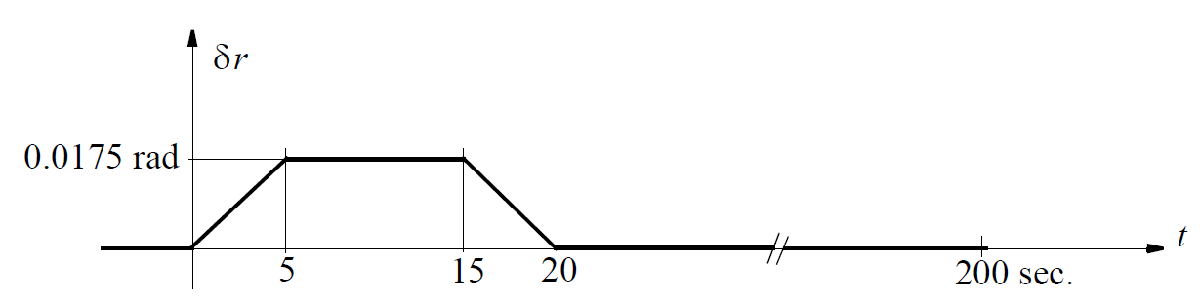

**Solution:**

The rudder time function can be made by combining four signals; the rising ramp, the steady value of 1, the decreasing ramp and the steady value 0. The Matlab code for making these signals and combining them to the rudder time function is shown in Algorithm 1. The rudder time function is input to the lsim()-function that returns a plot of the yaw rate. Notice that the input signal is also depicted in the plot-output from lsim():

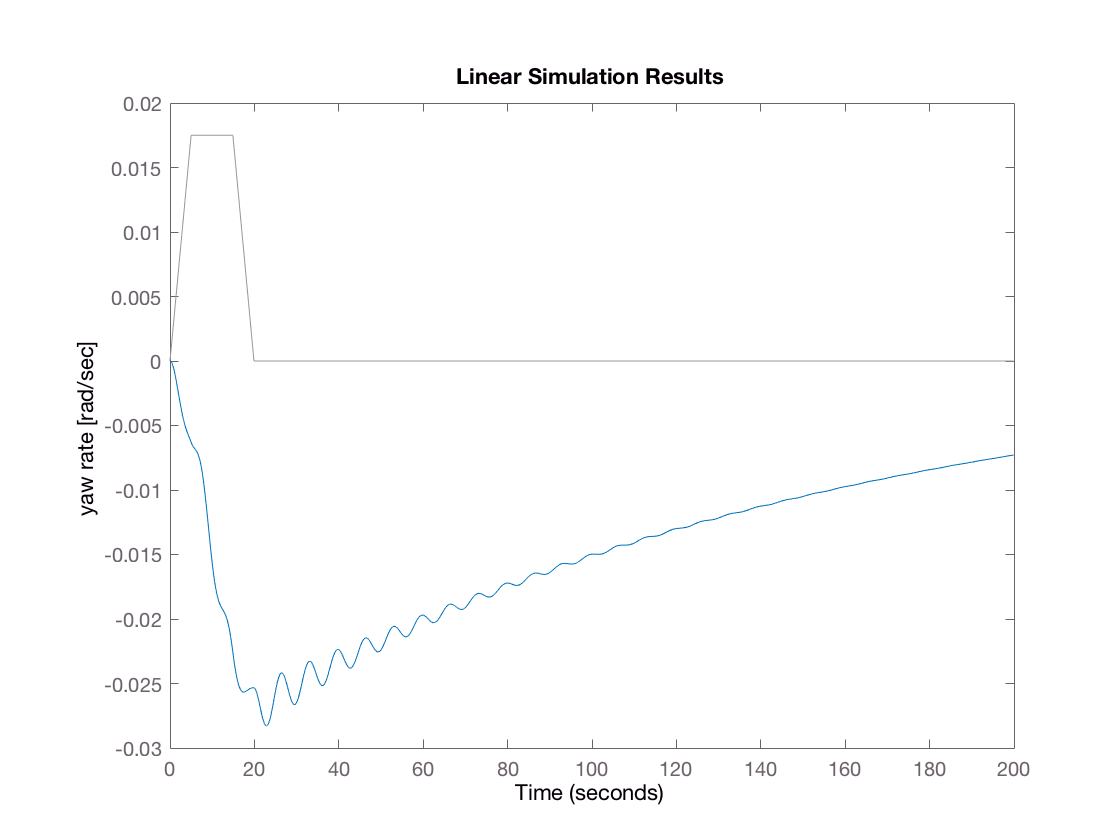

figure
t = 0:.1:199.9; % Time vector
ut1 = (0:50) * 0.0175/50; % Rising Ramp
ut2 = ones(1,98) * 0.0175; % Steady value of 1
ut3 = (0:50) * (-0.0175/50) + 0.0175; % Decreasing ramp
ut4 = zeros(1,1800); % Steady value of 0
uttot = [ut1 ut2 ut3 ut4]; % Rudder time function
x0 = [0 0 0 0]'; % Initial State
lsim(A,B,C,D,uttot,t,x0)
ylabel('yaw rate [rad/sec]');

From a rudder change of only 1 deg, it takes more than four minutes to converge back to the original track, this could be for the sake of the passengers, however the time it takes to settle also says something about the speed at which the airplane is able to navigate, which is rather slow. 